## 1. Read Simscape results

timeX  = out.x_tip.Time(:);
timeY  = out.y_tip.Time(:);
timeVy = out.vy_P.Time(:);
timeAy = out.ay_P.Time(:);

xMm = 1000 * out.x_tip.Data(:);  % mm
yMm = 1000 * out.y_tip.Data(:);  % mm
vy  = out.vy_P.Data(:);          % m/s
ay  = out.ay_P.Data(:);          % m/s^2

## 2. Calculate the analytical reference from Part II

xTheoryM  = (L23^2 - L5678^2) / (2 * L4);
xTheoryMm = 1000 * xTheoryM;

% Crank angle, angular velocity, and angular acceleration at time t
switch mode
    case 0  % Constant-speed sweep
        angleAt = @(t) -amplitude + crankRate * t;
        speedAt = @(t) crankRate * ones(size(t));
        accelAt = @(t) zeros(size(t));

    case 1  % Sinusoidal sweep
        angleAt = @(t) -amplitude * cos(omega * t);
        speedAt = @(t)  amplitude * omega * sin(omega * t);
        accelAt = @(t)  amplitude * omega^2 * cos(omega * t);

    otherwise
        error('Unsupported input mode. Use 0 or 1.');
end

% Evaluate each prediction at the timestamps of its measured signal
thetaVy = angleAt(timeVy);
thetaAy = angleAt(timeAy);
omegaAy = speedAt(timeAy);

dyDtheta = @(theta) (xTheoryM / 2) ./ cos(theta / 2).^2;

vyTheory = dyDtheta(thetaVy) .* speedAt(timeVy);
ayTheory = dyDtheta(thetaAy) .* ...
    (accelAt(timeAy) + tan(thetaAy / 2) .* omegaAy.^2);


## 3. Report maximum absolute deviations for Part III

maxHorizontalDeviation = max(abs(xMm - xTheoryMm));

ans = 53.0372

maxVerticalVelocityError = max(abs(vy - vyTheory));
maxVerticalAccelerationError = max(abs(ay - ayTheory));

fprintf('Maximum horizontal deviation: %.3e mm\n', ...
    maxHorizontalDeviation);

Maximum horizontal deviation: 5.906e-11 mm


fprintf('Maximum vertical velocity difference: %.3e m/s\n', ...
    maxVerticalVelocityError);

Maximum vertical velocity difference: 6.968e-14 m/s


fprintf('Maximum vertical acceleration difference: %.3e m/s^2\n', ...
    maxVerticalAccelerationError);

Maximum vertical acceleration difference: 8.470e-12 m/s^2


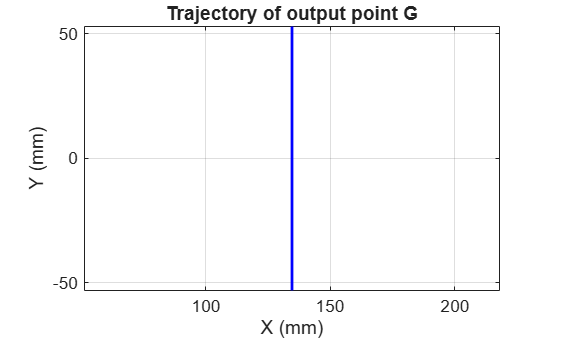


%% 4. Plot trajectory, position, velocity, and acceleration
figure('Name', 'Output trajectory');
plot(xMm, yMm, 'b-', 'LineWidth', 1.5);
axis equal;
grid on;
xlabel('X (mm)');
ylabel('Y (mm)');
title('Trajectory of output point G');

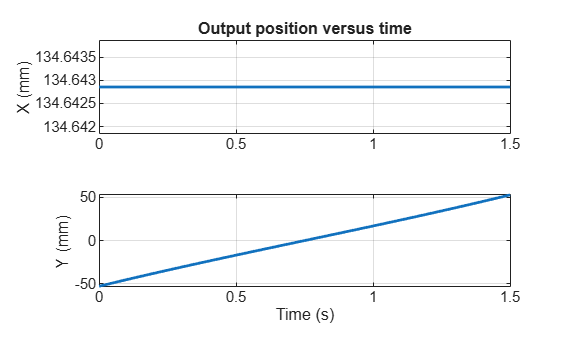


figure('Name', 'Output position');
positionLayout = tiledlayout(2, 1);

nexttile(positionLayout);
plot(timeX, xMm, 'LineWidth', 1.5);
xlim([timeX(1), timeX(end)]);
ylim(xTheoryMm + [-0.001, 0.001]);  % +/- 0.001 mm
grid on;
ylabel('X (mm)');
title('Output position versus time');

nexttile(positionLayout);
plot(timeY, yMm, 'LineWidth', 1.5);
xlim([timeY(1), timeY(end)]);
grid on;
xlabel('Time (s)');
ylabel('Y (mm)');

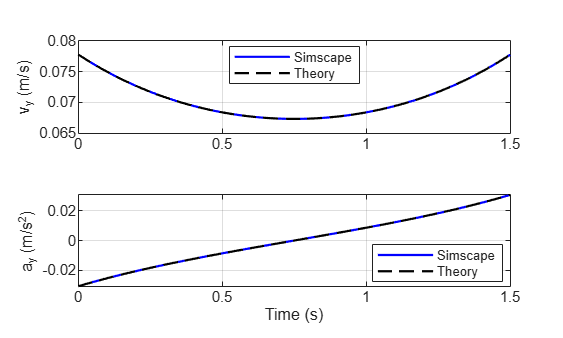


figure('Name', 'Vertical velocity and acceleration');
motionLayout = tiledlayout(2, 1);

nexttile(motionLayout);
plot(timeVy, vy, 'b-', timeVy, vyTheory, 'k--', 'LineWidth', 1.2);
grid on;
ylabel('v_y (m/s)');
legend('Simscape', 'Theory', 'Location', 'best');

nexttile(motionLayout);
plot(timeAy, ay, 'b-', timeAy, ayTheory, 'k--', 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('a_y (m/s^2)');
legend('Simscape', 'Theory', 'Location', 'best');

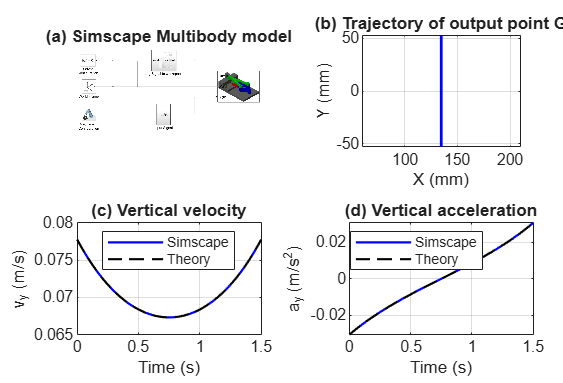


%% 5. Assemble the four-panel report figure
reportFig = figure('Name', 'Part III results', ...
    'Color', 'w', 'Position', [100 100 1000 680]);
reportLayout = tiledlayout(reportFig, 2, 2, ...
    'TileSpacing', 'compact', 'Padding', 'compact');

% (a) Simscape model
panel = nexttile(reportLayout);
image(panel, imread('Render.png'));
axis(panel, 'image');
axis(panel, 'off');
title(panel, '(a) Simscape Multibody model');

% (b) Output trajectory
panel = nexttile(reportLayout);
plot(panel, xMm, yMm, 'b-', 'LineWidth', 1.5);
axis(panel, 'equal');
grid(panel, 'on');
xlabel(panel, 'X (mm)');
ylabel(panel, 'Y (mm)');
title(panel, '(b) Trajectory of output point G');

% (c) Vertical velocity
panel = nexttile(reportLayout);
plot(panel, timeVy, vy, 'b-', timeVy, vyTheory, 'k--', 'LineWidth', 1.2);
xlim(panel, [timeVy(1), timeVy(end)]);
grid(panel, 'on');
xlabel(panel, 'Time (s)');
ylabel(panel, 'v_y (m/s)');
title(panel, '(c) Vertical velocity');
legend(panel, 'Simscape', 'Theory', 'Location', 'best');

% (d) Vertical acceleration
panel = nexttile(reportLayout);
plot(panel, timeAy, ay, 'b-', timeAy, ayTheory, 'k--', 'LineWidth', 1.2);
xlim(panel, [timeAy(1), timeAy(end)]);
grid(panel, 'on');
xlabel(panel, 'Time (s)');
ylabel(panel, 'a_y (m/s^2)');
title(panel, '(d) Vertical acceleration');
legend(panel, 'Simscape', 'Theory', 'Location', 'best');